# Example: Application of the function ASD to a bridge computational model

## Data set considered

The data set has been generated using the following Matlab file Exchange submission: [https://www.mathworks.com/matlabcentral/fileexchange/66016-response-of-a-line-like-structure-to-a-random-load](https://www.mathworks.com/matlabcentral/fileexchange/66016-response-of-a-line-like-structure-to-a-random-load)

The data set corresponds to three time series Do, Vo and Ao.  The vectors Ao, Vo and  Do correspond to the vertical  acceleration, velocity and displacement response of a computational suspension bridge model, respectively. The vector t is the time vector, expressed in seconds.

The numerical implementation of the DFT in the function ASD is partly inspired by the following code:             

[https://www.mathworks.com/matlabcentral/answers/21700-finding-the-velocity-from-displacement#answer_33902](https://www.mathworks.com/matlabcentral/answers/21700-finding-the-velocity-from-displacement#answer_33902)

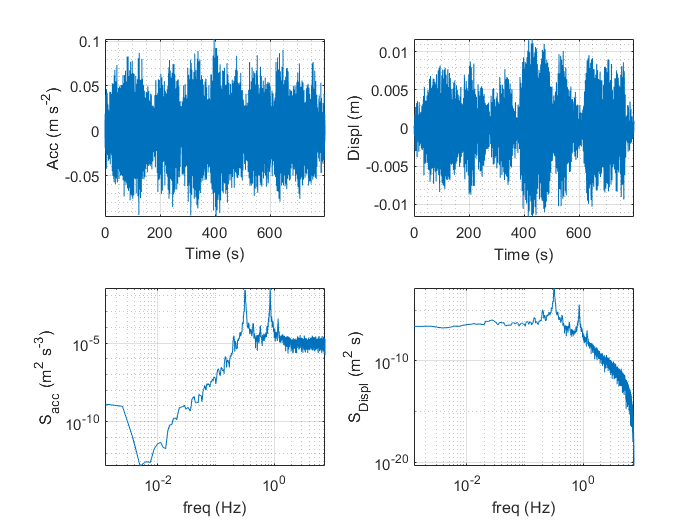

clearvars;close all;clc;
load('data_bridge.mat','Ao','Do','Vo','t');

% Remove the mean values
Do = detrend(Do,'constant'); % vertical bridge displacement at midspan
Ao = detrend(Ao,'constant'); % vertical bridge  acceleration at midspan 
Vo = detrend(Vo,'constant'); % vertical bridge velocity at midspan 


N = numel(t);
dt = median(diff(t));
fs = 1/dt;
[SDo,~]=pmtm(Do,4,N,fs);
[SAo,f]=pmtm(Ao,4,N,fs);
[SVo,f]=pmtm(Vo,4,N,fs);

figure
set(gcf,'color','w')

% Plot time series of the acceleration response at midspan
subplot(2,2,1)
plot(t,Ao);
xlabel('Time (s)')
ylabel('Acc (m s^{-2})')
axis tight
grid on
grid minor

% Plot time series of the displacement response at midspan
subplot(2,2,2)
plot(t,Do);
xlabel('Time (s)')
ylabel('Displ (m)')
axis tight
grid on
grid minor

% PSD of the acceleration response spectrum
subplot(2,2,3)
loglog(f,SAo);
xlabel('freq (Hz)')
ylabel('S_{acc} (m^2 s^{-3})')
axis tight
grid on
grid minor

% PSD of the displacement response spectrum
subplot(2,2,4)
loglog(f,SDo);
xlabel('freq (Hz)')
ylabel('S_{Displ} (m^2 s)')

axis tight
grid on
grid minor

## Case 1: From acceleration to displacement

indIn = 3; % Acceleration  
indOut = 1; % Displacement

tic
y1 =  ASD(Ao,dt, indIn, indOut,'zeropadding',0); % fft method
y2 =  ASD(Ao,dt, indIn, indOut,'zeropadding',1); % fft method
y3 =  ASD(Ao,dt, indIn, indOut,'method','TD'); % cumtrapz
toc

Elapsed time is 0.205281 seconds.


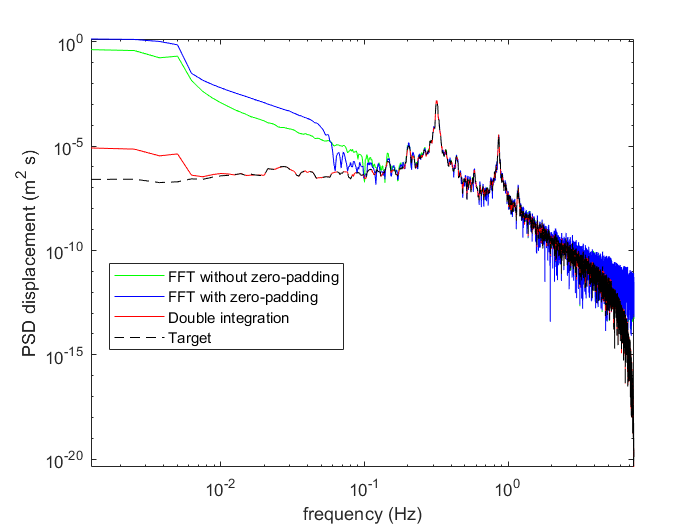


[SD1,f]=pmtm(y1,4,N,fs);
[SD2,~]=pmtm(y2,4,N,fs);
[SD3,~]=pmtm(y3,4,N,fs);

clf;close all
figure
loglog(f,SD1,'g',f,SD2,'b',f,SD3,'r')
hold on
loglog(f,SDo,'k--');
legend('FFT without zero-padding','FFT with zero-padding','Double integration','Target','location','best')
axis tight
set(gcf,'color','w')
xlabel('frequency (Hz)')
ylabel('PSD displacement (m^2 s)')

## Case 2: From displacement to acceleration

indIn = 1; % Displacement
indOut = 3; % Acceleration

tic
y1 =  ASD(Do,dt, indIn, indOut,'zeropadding',0); % fft method
y2 =  ASD(Do,dt, indIn, indOut,'zeropadding',1); % fft method
y3 =  ASD(Do,dt, indIn, indOut,'zeropadding',1,'method','TD'); % derivation with right-hand differences
toc

Elapsed time is 0.033340 seconds.


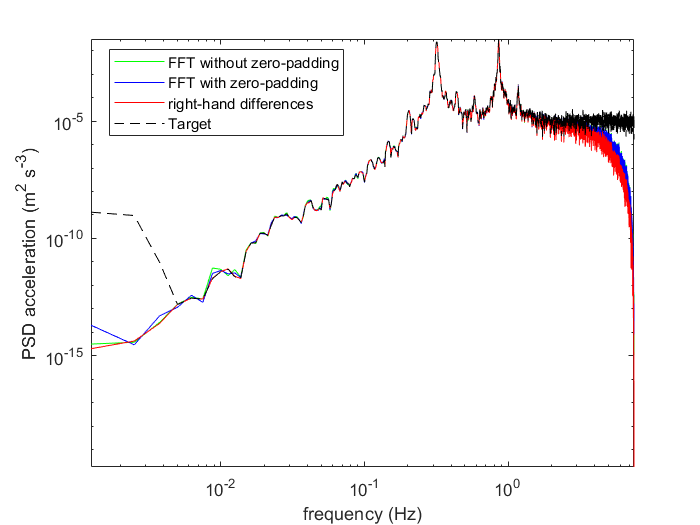


[SA1,f]=pmtm(y1,4,N,fs);
[SA2,~]=pmtm(y2,4,N,fs);
[SA3,~]=pmtm(y3,4,N,fs);

clf;close all
figure
loglog(f,SA1,'g',f,SA2,'b',f,SA3,'r')
hold on
loglog(f,SAo,'k--');
legend('FFT without zero-padding','FFT with zero-padding','right-hand differences','Target','location','best')
axis tight
set(gcf,'color','w')
xlabel('frequency (Hz)')
ylabel('PSD acceleration (m^2 s^{-3})')

## Case 3: From acceleration to velocity

indIn = 3; % Displacement
indOut = 2; % Acceleration

tic
y1 =  ASD(Ao,dt, indIn, indOut,'zeropadding',0); % fft method
y2 =  ASD(Ao,dt, indIn, indOut,'zeropadding',1); % fft method
y3 =  ASD(Ao,dt, indIn, indOut,'zeropadding',1,'method','TD'); % derivation with right-hand differences
toc

Elapsed time is 0.036360 seconds.


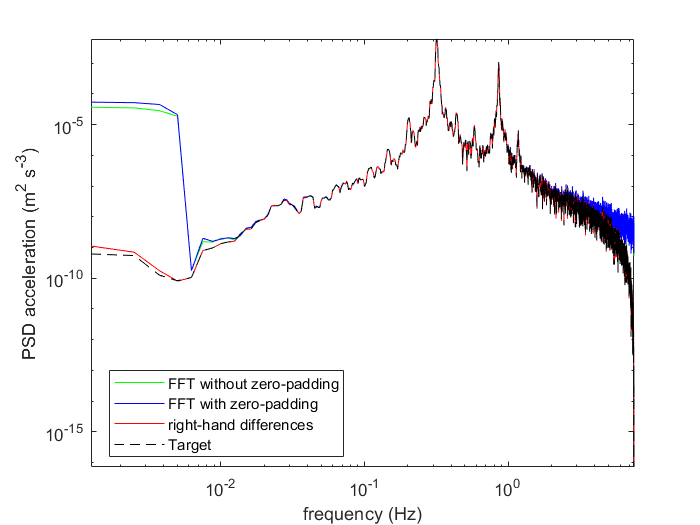


[SV1,f]=pmtm(y1,4,N,fs);
[SV2,~]=pmtm(y2,4,N,fs);
[SV3,~]=pmtm(y3,4,N,fs);

clf;close all
figure
loglog(f,SV1,'g',f,SV2,'b',f,SV3,'r')
hold on
loglog(f,SVo,'k--');
legend('FFT without zero-padding','FFT with zero-padding','right-hand differences','Target','location','best')
axis tight
set(gcf,'color','w')
xlabel('frequency (Hz)')
ylabel('PSD acceleration (m^2 s^{-3})')

## Conclusions

When transforming acceleration data into displacement data, the scientific literature often mentions that the double integration technique should be avoided in favor of the method based on the discrete Fourier transform (DFT). This is a statement that might be considered as an established truth for manys structures 

The double-integration technique can be performed with or without systematic removal of the linear trends. In the present case, the linear trend was removed before each application of the cumulative trapezoidal numerical integration, limiting propagation of numerical errors. This led to better performance of the double-integration technique than with the DFT. Similarly, when transforming displacement data into acceleration data, the right-hand difference technique was slightly better than the application of the DFT on the displacement signal. The lower error observed may be linked to the use of simulated data. So the present results should be interpreted with cautions. 